syms theta(t) theta_0 theta_t0
syms phi t
m = 1

m = 1

I = 1

I = 1

g= -9.8

g = -9.8000

l = 1

l = 1

C_f = 1

C_f = 1



eqn = diff(theta,2) == (g*l*m *sin(theta) + C_f * diff(theta,1))*I

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right)-\frac{49\,\sin\left(\theta \left(t\right)\right)}{5}$$

theta_t = diff(theta,1)

$$theta\_t(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

cond = [theta(0)== pi/2,theta_t(0)==0]

$$cond = \left(\begin{array}{cc} \theta \left(0\right)=\frac{\pi }{2} & \left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

eqn = diff(theta,2)*I +(g*l*m *theta - C_f * diff(theta,1))*I

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right)-\frac{49\,\theta \left(t\right)}{5}$$

syms t s
syms theta(t) Theta
lap_eqn = laplace(eqn, t, s);

%eqn = diff(theta,2)*I +C_f *diff(theta) - g*l*m * theta
l_eqn = laplace(eqn)

$$l\_eqn = \theta \left(0\right)-s\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)-s\,\theta \left(0\right)-\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)-\frac{49\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)}{5}$$

syms theta_s t s

subs(l_eqn, laplace(theta(t), t, s), Theta);
lap_eqn_subs = subs(l_eqn, laplace(theta(t), t, s), Theta)/Theta;
lap_eqn_subs

$$lap\_eqn\_subs = -\frac{\frac{49\,\Theta }{5}-\theta \left(0\right)+\Theta \,s+s\,\theta \left(0\right)+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}{\Theta }$$

s_tf = tf('s')


s_tf =
 
  s
 
Continuous-time transfer function.


lap_eqn_sub = subs(lap_eqn_subs,theta(0),0)

$$lap\_eqn\_sub = -\frac{\frac{49\,\Theta }{5}+\Theta \,s+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}{\Theta }$$


expand(1/lap_eqn_subs)

$$ans = -\frac{\Theta }{\frac{49\,\Theta }{5}-\theta \left(0\right)+\Theta \,s+s\,\theta \left(0\right)+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}$$


eqn_cancled = 1/(49/5- pi/2 + s_tf/10 + s_tf^2)


eqn_cancled =
 
          10
  ------------------
  10 s^2 + s + 82.29
 
Continuous-time transfer function.


eqn_cancled = eqn_cancled/(1+eqn_cancled)


eqn_cancled =
 
             100 s^2 + 10 s + 822.9
  --------------------------------------------
  100 s^4 + 20 s^3 + 1747 s^2 + 174.6 s + 7595
 
Continuous-time transfer function.


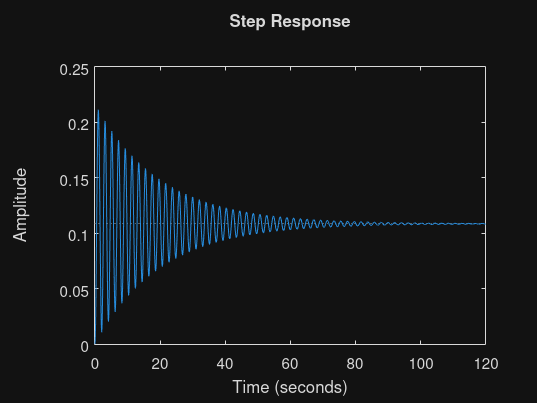

step(eqn_cancled)

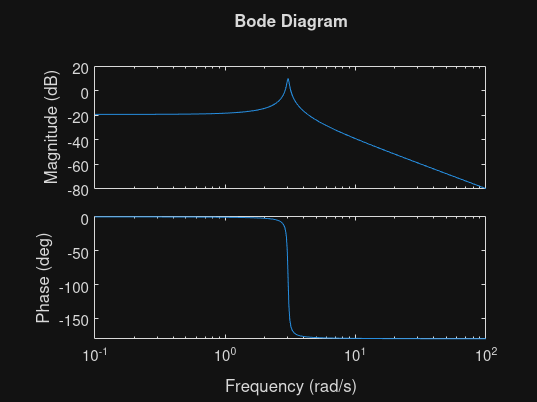

bode(eqn_cancled)